clear; clc; close all;
X_train = loadMNISTImages("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\update_2\code\data\MNIST\train-images.idx3-ubyte");
y_train = loadMNISTLabels("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\update_2\code\data\MNIST\train-labels.idx1-ubyte");
X_test  = loadMNISTImages("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\update_2\code\data\MNIST\t10k-images.idx3-ubyte");
y_test  = loadMNISTLabels("C:\Users\bhupa\Videos\MFC\C3_MFC4_LowRankTrainingOfDNNs\update_2\code\data\MNIST\t10k-labels.idx1-ubyte");

Y_train = oneHotEncode(y_train,10);
Y_test  = oneHotEncode(y_test,10);
d0 = 784; d1 = 128; d2 = 64; d3 = 10;

r1 = min(d1,d0);
r2 = min(d2,d1);
r3 = min(d3,d2);

rng(1);

[U1,~] = qr(randn(d1,r1),0);
[V1,~] = qr(randn(d0,r1),0);
alpha1 = randn(r1,1);

[U2,~] = qr(randn(d2,r2),0);
[V2,~] = qr(randn(d1,r2),0);
alpha2 = randn(r2,1);

[U3,~] = qr(randn(d3,r3),0);
[V3,~] = qr(randn(d2,r3),0);
alpha3 = randn(r3,1);

epochs = 100;
batch_size = 128;
lr = 1e-3;
lambda_orth = 1e-3;
lambda_sparse = 1e-3;
threshold = 1e-4;

N = size(X_train,2);
num_batches = floor(N/batch_size);

loss_hist = zeros(epochs,1);
prev_loss = inf;
useSVD = true;

for epoch = 1:epochs

    perm = randperm(N);
    epoch_loss = 0;

    for b = 1:num_batches

        idx = perm((b-1)*batch_size+1 : b*batch_size);
        X = X_train(:,idx);
        Y = Y_train(:,idx);
        m = size(X,2);

        if useSVD

            
            s1 = exp(alpha1); S1 = diag(sqrt(s1));
            s2 = exp(alpha2); S2 = diag(sqrt(s2));
            s3 = exp(alpha3); S3 = diag(sqrt(s3));

            H1 = S1*(V1'*X);  Z1 = U1*S1*H1;  A1 = max(0,Z1);
            H2 = S2*(V2'*A1); Z2 = U2*S2*H2;  A2 = max(0,Z2);
            H3 = S3*(V3'*A2); Z3 = U3*S3*H3;

        else

            
            Z1 = W1*X + b1; A1 = max(0,Z1);
            Z2 = W2*A1 + b2; A2 = max(0,Z2);
            Z3 = W3*A2 + b3;

        end

        Z3 = Z3 - max(Z3,[],1);
        Yhat = exp(Z3)./sum(exp(Z3),1);

        CE = -sum(sum(Y.*log(Yhat)))/m;

        if useSVD
            Orth = norm(U1'*U1-eye(size(U1,2)),'fro')^2 + ...
                   norm(V1'*V1-eye(size(V1,2)),'fro')^2 + ...
                   norm(U2'*U2-eye(size(U2,2)),'fro')^2 + ...
                   norm(V2'*V2-eye(size(V2,2)),'fro')^2 + ...
                   norm(U3'*U3-eye(size(U3,2)),'fro')^2 + ...
                   norm(V3'*V3-eye(size(V3,2)),'fro')^2;

            Sparse = norm(s1,1)/norm(s1,2) + ...
                     norm(s2,1)/norm(s2,2) + ...
                     norm(s3,1)/norm(s3,2);

            loss = CE + lambda_orth*Orth + lambda_sparse*Sparse;
        else
            loss = CE;
        end

        epoch_loss = epoch_loss + loss;

       

        dZ3 = Yhat - Y;

        if useSVD
            

            dU3 = (dZ3*(S3*H3)')/m;
            dH3 = (U3*S3)'*dZ3;
            dV3 = (A2*(dH3'*S3))/m;
            ds3 = diag((U3'*dZ3)*H3')/m;

            dA2 = V3*(S3*dH3);
            dZ2 = dA2 .* (Z2>0);

            dU2 = (dZ2*(S2*H2)')/m;
            dH2 = (U2*S2)'*dZ2;
            dV2 = (A1*(dH2'*S2))/m;
            ds2 = diag((U2'*dZ2)*H2')/m;

            dA1 = V2*(S2*dH2);
            dZ1 = dA1 .* (Z1>0);

            dU1 = (dZ1*(S1*H1)')/m;
            dH1 = (U1*S1)'*dZ1;
            dV1 = (X*(dH1'*S1))/m;
            ds1 = diag((U1'*dZ1)*H1')/m;

            alpha1 = alpha1 - lr*(ds1.*s1);
            alpha2 = alpha2 - lr*(ds2.*s2);
            alpha3 = alpha3 - lr*(ds3.*s3);

            U1 = U1 - lr*dU1; V1 = V1 - lr*dV1;
            U2 = U2 - lr*dU2; V2 = V2 - lr*dV2;
            U3 = U3 - lr*dU3; V3 = V3 - lr*dV3;

        else
            

            dW3 = (dZ3*A2')/m; db3 = sum(dZ3,2)/m;
            dA2 = W3'*dZ3; dZ2 = dA2.*(Z2>0);
            dW2 = (dZ2*A1')/m; db2 = sum(dZ2,2)/m;
            dA1 = W2'*dZ2; dZ1 = dA1.*(Z1>0);
            dW1 = (dZ1*X')/m; db1 = sum(dZ1,2)/m;

            W3 = W3 - lr*dW3; b3 = b3 - lr*db3;
            W2 = W2 - lr*dW2; b2 = b2 - lr*db2;
            W1 = W1 - lr*dW1; b1 = b1 - lr*db1;
        end

        

        grad_diff = abs(prev_loss - loss);

        if useSVD && grad_diff < threshold
            fprintf("Switching to FULL DNN at epoch %d\n",epoch);

            W1 = U1*diag(sqrt(exp(alpha1)))*V1';
            W2 = U2*diag(sqrt(exp(alpha2)))*V2';
            W3 = U3*diag(sqrt(exp(alpha3)))*V3';

            b1 = zeros(d1,1);
            b2 = zeros(d2,1);
            b3 = zeros(d3,1);

            useSVD = false;
        end

        prev_loss = loss;

    end

    loss_hist(epoch) = epoch_loss/num_batches;
    fprintf("Epoch %d | Loss %.4f\n",epoch,loss_hist(epoch));
end

Epoch 1 | Loss 1.3523
Epoch 2 | Loss 0.7509
Epoch 3 | Loss 0.5674
Epoch 4 | Loss 0.4763
Epoch 5 | Loss 0.4258
Epoch 6 | Loss 0.3927
Epoch 7 | Loss 0.3685
Epoch 8 | Loss 0.3498
Epoch 9 | Loss 0.3335
Epoch 10 | Loss 0.3199
Epoch 11 | Loss 0.3083
Epoch 12 | Loss 0.2989
Epoch 13 | Loss 0.2890
Epoch 14 | Loss 0.2809
Epoch 15 | Loss 0.2729
Epoch 16 | Loss 0.2664
Epoch 17 | Loss 0.2597
Epoch 18 | Loss 0.2534
Epoch 19 | Loss 0.2473
Epoch 20 | Loss 0.2422
Epoch 21 | Loss 0.2368
Epoch 22 | Loss 0.2323
Epoch 23 | Loss 0.2273
Epoch 24 | Loss 0.2225
Epoch 25 | Loss 0.2185
Epoch 26 | Loss 0.2147
Epoch 27 | Loss 0.2110
Epoch 28 | Loss 0.2072
Epoch 29 | Loss 0.2037
Epoch 30 | Loss 0.2003
Epoch 31 | Loss 0.1972
Epoch 32 | Loss 0.1941
Epoch 33 | Loss 0.1913
Epoch 34 | Loss 0.1888
Epoch 35 | Loss 0.1857


Switching to FULL DNN at epoch 36


Epoch 36 | Loss 0.3384
Epoch 37 | Loss 0.7445
Epoch 38 | Loss 0.5613
Epoch 39 | Loss 0.4698
Epoch 40 | Loss 0.4154
Epoch 41 | Loss 0.3792
Epoch 42 | Loss 0.3536
Epoch 43 | Loss 0.3341
Epoch 44 | Loss 0.3192
Epoch 45 | Loss 0.3070
Epoch 46 | Loss 0.2970
Epoch 47 | Loss 0.2882
Epoch 48 | Loss 0.2810
Epoch 49 | Loss 0.2744
Epoch 50 | Loss 0.2690
Epoch 51 | Loss 0.2639
Epoch 52 | Loss 0.2593
Epoch 53 | Loss 0.2552
Epoch 54 | Loss 0.2514
Epoch 55 | Loss 0.2478
Epoch 56 | Loss 0.2446
Epoch 57 | Loss 0.2415
Epoch 58 | Loss 0.2388
Epoch 59 | Loss 0.2361
Epoch 60 | Loss 0.2337
Epoch 61 | Loss 0.2313
Epoch 62 | Loss 0.2291
Epoch 63 | Loss 0.2269
Epoch 64 | Loss 0.2249
Epoch 65 | Loss 0.2230
Epoch 66 | Loss 0.2211
Epoch 67 | Loss 0.2194
Epoch 68 | Loss 0.2176
Epoch 69 | Loss 0.2158
Epoch 70 | Loss 0.2142
Epoch 71 | Loss 0.2125
Epoch 72 | Loss 0.2111
Epoch 73 | Loss 0.2098
Epoch 74 | Loss 0.2084
Epoch 75 | Loss 0.2069
Epoch 76 | Loss 0.2054
Epoch 77 | Loss 0.2042
Epoch 78 | Loss 0.2030
Epoch 79 | 


Z1 = W1*X_test + b1; A1 = max(0,Z1);
Z2 = W2*A1 + b2; A2 = max(0,Z2);
Z3 = W3*A2 + b3;

[~,pred] = max(Z3,[],1);
pred = pred - 1;

acc = mean(pred'==y_test)*100;
fprintf("Final Accuracy: %.2f%%\n",acc);

Final Accuracy: 94.73%


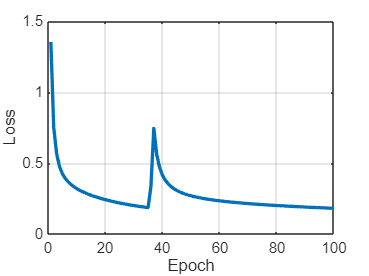



figure; plot(loss_hist,'LineWidth',2);
xlabel('Epoch'); ylabel('Loss'); grid on;

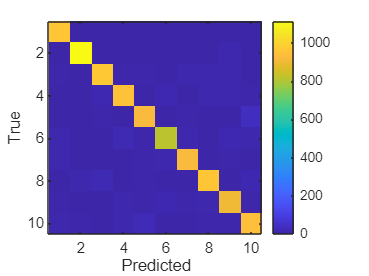


conf_mat = zeros(10,10);
for i=1:length(y_test)
    conf_mat(y_test(i)+1,pred(i)+1) = ...
        conf_mat(y_test(i)+1,pred(i)+1)+1;
end

figure; imagesc(conf_mat);
colorbar; xlabel('Predicted'); ylabel('True');
axis square;

function images = loadMNISTImages(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numImages = fread(fid, 1, 'int32', 0, 'ieee-be');
    numRows = fread(fid, 1, 'int32', 0, 'ieee-be');
    numCols = fread(fid, 1, 'int32', 0, 'ieee-be');

    images = fread(fid, inf, 'unsigned char');
    fclose(fid);

    images = reshape(images, numCols * numRows, numImages);
    images = double(images) / 255;
end

function labels = loadMNISTLabels(filename)
    fid = fopen(filename, 'rb');

    magic = fread(fid, 1, 'int32', 0, 'ieee-be');
    numLabels = fread(fid, 1, 'int32', 0, 'ieee-be');

    labels = fread(fid, inf, 'unsigned char');
    fclose(fid);

    labels = double(labels);
end
function Y = oneHotEncode(y, numClasses)
    Y = zeros(numClasses, length(y));
    for i = 1:length(y)
        Y(y(i)+1, i) = 1;
    end
end